### 2. Συμπίεση Εικόνας με χρήση μετασχηματισμού DCT 

### ΠΡΟΕΠΕΞΕΡΓΑΣΙΑ

Φορτώνεται ο πίνακας flower.mat ο οποίος είναι 256χ256 και έπειτα γίνεται  ο τεμαχισμός σε 64 πίνακες 32χ32 διαστασεων.

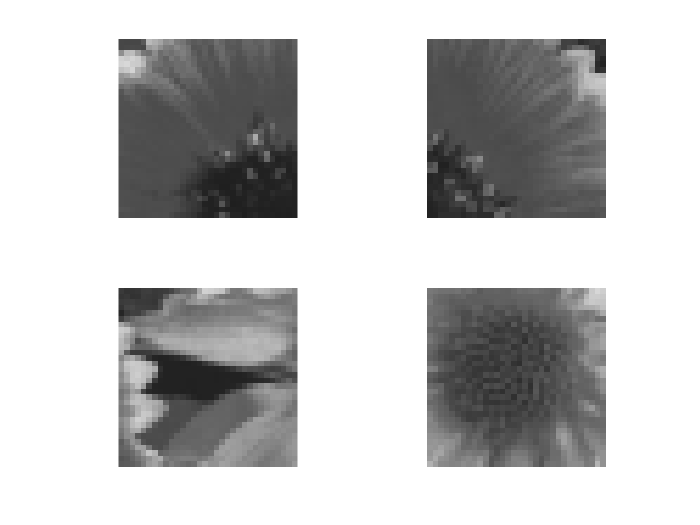

clc
clear all
load('images\2\flower.mat')
counter1=-32;
counter2=0;
A={};
A_dct={};
flower_2dct=zeros(256,256);
flower_2dct_original=dct2(flower);
for k=1:64
    if mod(k,8)==1
        counter1=counter1+32;
        counter2=0; 
    end
    A{k}=flower(1+counter1:32+counter1,1+counter2:32+counter2);
    A_dct{k}=dct2(A{k});
    %flower_2dct(1+counter1:32+counter1,1+counter2:32+counter2)=dct2(A{k});
    %flower_cut(1+counter1:32+counter1,1+counter2:32+counter2)=A{k};
    counter2=counter2+32;
end

figure()
for p=10:13
    subplot(2,2,p-9)
    imshow(A{p})
end

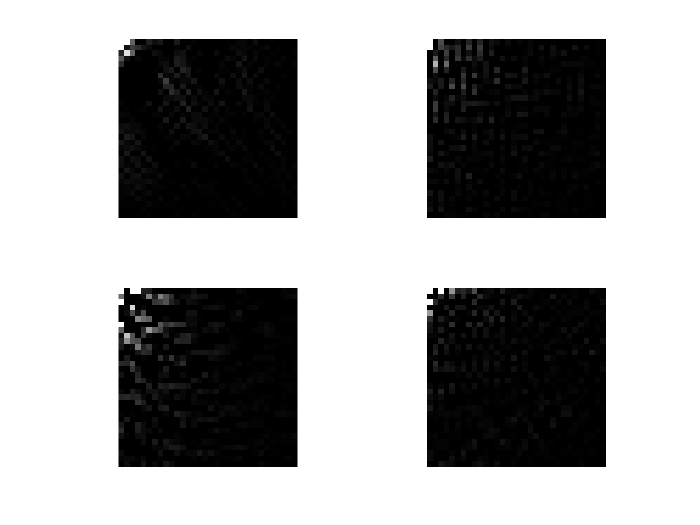

figure()
for p=10:13
    subplot(2,2,p-9)
    imshow(A_dct{p})
end

προκύπτει ένα struct A το οποίο περιέχει 64 cells τα οποία περιέχουν πίνακες 32χ32 έπειτα από τον τεμαχισμό της εικόνας.

Εφαρμόζεται μετασχηματισμός 2D DCT μέσω της συνάρτησης **dct2()** σε κάθε κελί του struct A  και οι τιμές που προκύπτουν για κάθε πίνακα τοποθετούνται σε ένα δεύετρο sruct A_dct. O A_dct περιέχει ολους τους μετασχηματισμούς των πίνακων  32χ32 DCT σε κάθε κελί του . Ενδεικτικά παρουσιάζονται κάποια κομμάτια της εικόνας (πίνακες των 32χ32) και οι αντίστοιχοι μετασχηματισμένοι dct πίνακες .

**2)ΕΠΙΛΟΓΗ ΓΙΑ ΥΠΟΣΥΝΟΛΟ ΣΥΝΤΕΛΕΣΤΩΝ ΜΕ ΤΗΝ ΜΕΘΟΔΟΥ ΖΩΝΗΣ.**

επιλέγω r=40/100 άρα θα χρειαστώ τα Ν=round(0.4*32*32)=round(409.6)=410 και δημιουργώ μία μάσκα περίπου 20χ20 που αντιστοιχεί στο 39.06/100   με αυτά τα στοιχεία η οποία θα εφαρμόζεται στη πάνω αριστερά γωνία της κάθε μετασχηματισμένης με 2d dct εικόνας των 32x32 .

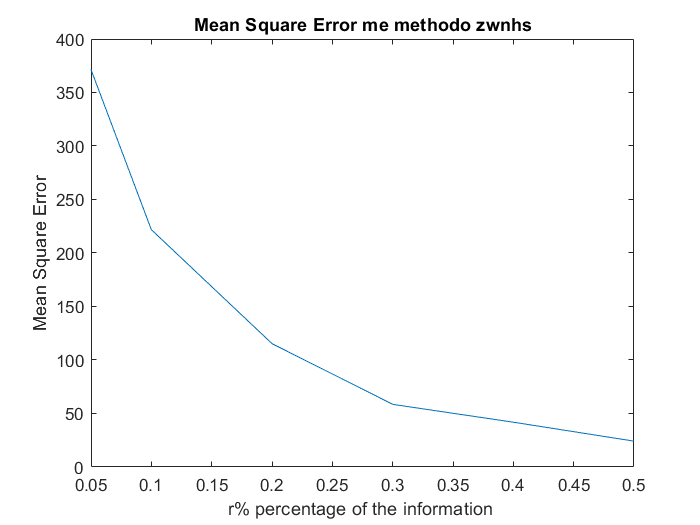


B1={};
B_idct_zwnhs={};
r=[0.05 0.1 0.2 0.3 0.4 0.5];
MSE_zwnhs_mat=[];
for k=1:length(r)
    MSE_zwnhs=0;
    N=(round(sqrt(r(k)*32*32)))^2; % megethos maskas 
    temp=zeros(32,32);
    temp(1:sqrt(N),1:sqrt(N))=1;
    for i=1:64
        B1{i}=temp.*A_dct{i};
        B_idct_zwnhs{i+(k-1)*64}=idct2(B1{i});
        for m=1:32
            for n=1:32
                MSE_zwnhs=(A{i}(m,n)-B_idct_zwnhs{i+(k-1)*64}(m,n))^2+MSE_zwnhs;  
            end
        end
    end
    MSE_zwnhs_mat=[MSE_zwnhs_mat MSE_zwnhs];
end  

[min_mse_zwnhs,idx_zwnhs]=min(MSE_zwnhs_mat);
B_idct_zwnhs_best={};
for i=1:64
    B_idct_zwnhs_best{i}=B_idct_zwnhs{(idx_zwnhs-1)*64+i};
end
figure()
plot(r,MSE_zwnhs_mat);
title('Mean Square Error me methodo zwnhs')
ylabel("Mean Square Error");
xlabel("r% percentage of the information ");

Οπότε η επιλογή για το υποσύνολο των συνετλεστών προκύπτει για r=0.5

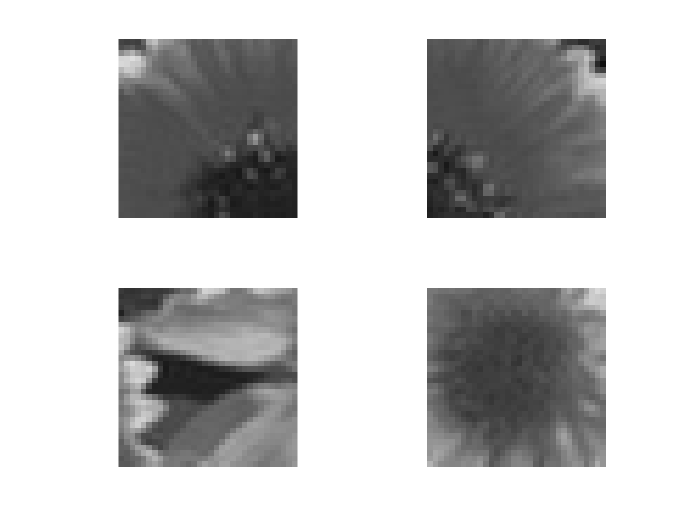

figure()
for p=10:13
    subplot(2,2,p-9)
    imshow(B_idct_zwnhs_best{p})
end

** ΕΠΙΛΟΓΗ ΓΙΑ ΥΠΟΣΥΝΟΛΟ ΣΥΝΤΕΛΕΣΤΩΝ ΜΕ ΤΗΝ ΜΕΘΟΔΟΥ ΤΟΥ ΚΑΤΩΦΛΙΟΥ.**

επιλέγω r=40/100 άρα θα χρειαστώ τα Ν=round(0.4*32*32)=round(409.6)=410 μεγαλύτερα στοιχεία κάθε φορά απο τους πίνακες 32χ32 αυτά τα αφήνω στις θέσεις που ήταν ενώ όλα τα άλλα 1024-410=614 τα θέτω 0 στις θέσεις που ήταν.

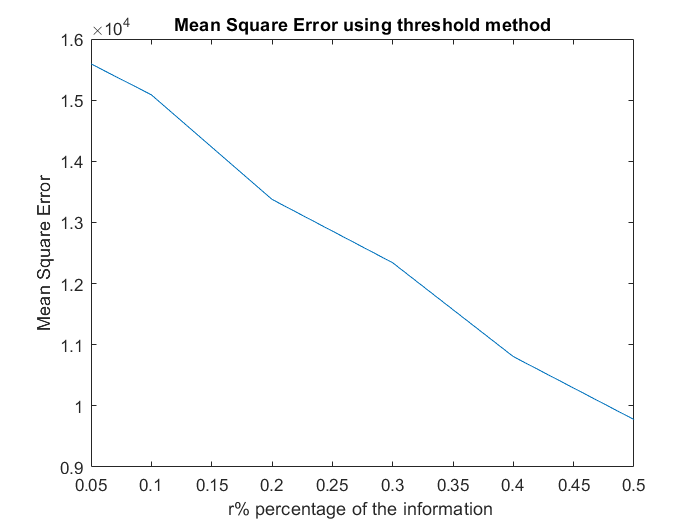

B2={};
B_idct_threshold={};
MSE_threshold_mat=[];

r=[0.05 0.1 0.2 0.3 0.4 0.5];
for p=1:length(r)
    N=round(r(p)*32*32);
    MSE_threshold=0;
    for k=1:length(A)
        temp=zeros(32,32); 
        [max_mat,idx]=sort(abs(A{k}(:)),'descend');
        max_mat=max_mat(1:N);
        
        for i=1:N
            temp(idx(i))=A_dct{k}(idx(i));
        end
        B2{k}=temp;
        B_idct_threshold{k+(p-1)*64}=idct2(B2{k});
        for m=1:32
            for n=1:32
                MSE_threshold=(A{k}(m,n)-B_idct_threshold{k+(p-1)*64}(m,n))^2+MSE_threshold;  
            end
        end
        
    end
    MSE_threshold_mat=[MSE_threshold_mat MSE_threshold];
end
[min_mse_thr,idx_thres]=min(MSE_threshold_mat);
B_idct_threshold_best={};
for i=1:64
    B_idct_threshold_best{i}=B_idct_threshold{(idx_thres-1)*64+i};
end
figure()
plot(r,MSE_threshold_mat);
title('Mean Square Error using threshold method')
ylabel("Mean Square Error");
xlabel("r% percentage of the information ");

Οπότε η επιλογή για το υποσύνολο των συνετλεστών προκύπτει για r=0.5

Δημιουργήθηκε ένα δέυτερο struct B το οποίο περιέχει και τους 64  32χ32 πινακες έναν σε κάθε κελί , μόνο που ο κάθε πίνακας περιέχει Ν=410 μη μηδενικούς όρους οι οποίοι Ν είναι και οι μέγιστοι ( κάθε φορά αντιστοιχούν στον πίνακα max_mat και οι θέσεις τους στον idx ) .Αυτό γίνεται μέσω ενός πίνακα temp που δρα ως μασκα δηλαδή πολλαπλασιάζει κάθε στοιχείο που δεν ανήκει στα 40 μέγιστα με 0 ενω τα υπόλοιπα με 1.  Έπειτα εφαρμόζουμε αντίστρο DCT---> IDCT και έτσι προκύπτει η συμπιεσμένη εικόνα που είναι τα 64 κελιά του struct  B_idct_threshold_best.

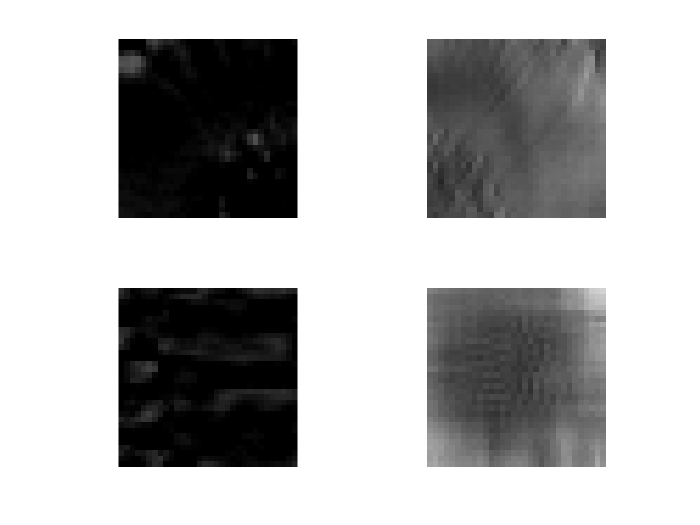

figure()
for p=10:13
    subplot(2,2,p-9)
    imshow(B_idct_threshold_best{p})
end